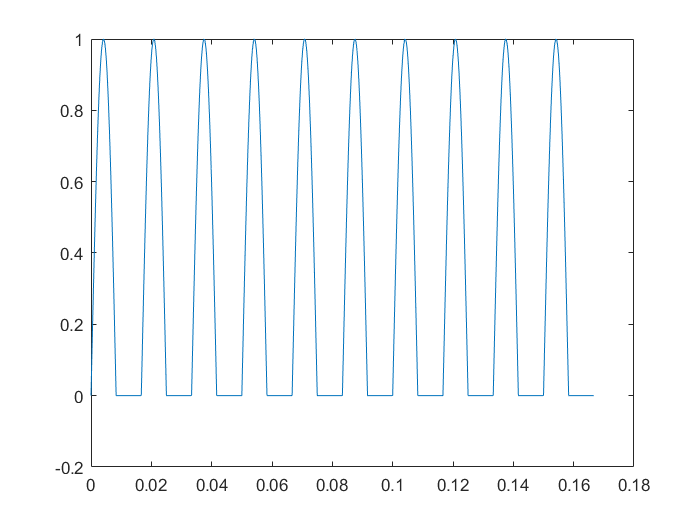

f0=60;
T0=1/f0;
dt=1/(100*f0);
time=0:dt:10*T0;
x=f(time);
plot(time,x);

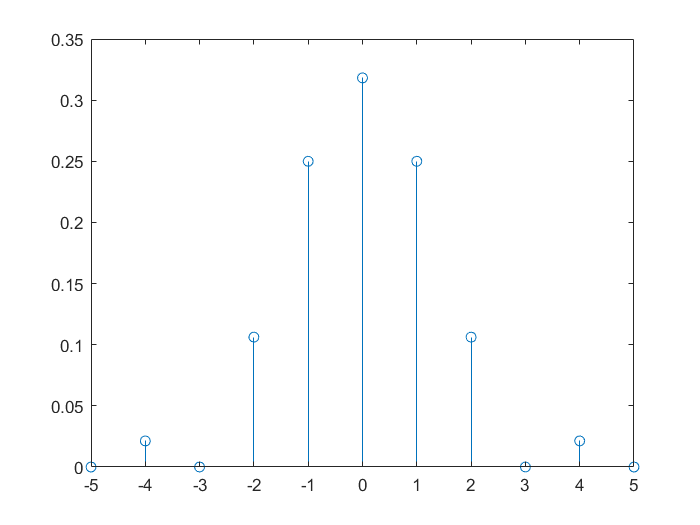


DC=dt*sum(f(time))/(10*T0);
index=1;
for k=-3:3
% Notice that this expression is also valid for k=0
    c_60(index)=dt*sum(x.*exp(-1i*k*2*pi*time/T0))/(10*T0);
% Or equivalently: c(index)=mean(x.*exp(-1i*k*2*pi*t/T0));
    index=index+1;
end
%     c=[c_m3 c_m2 c_m1 c_m0 c_1 c_2 c_3]
% index=  1    2    3    4    5   6   7

c_120=c_60;
index_2=1;
for j=-5:5
    c_60_2(index_2)=dt*sum(x.*exp(-1i*j*2*pi*time/T0))/(10*T0);
    index_2=index_2+1;
end

magnitude=abs(c_60_2);
phase=angle(c_60_2);
n=5;
k=-n:n;

figure
stem(k,magnitude)

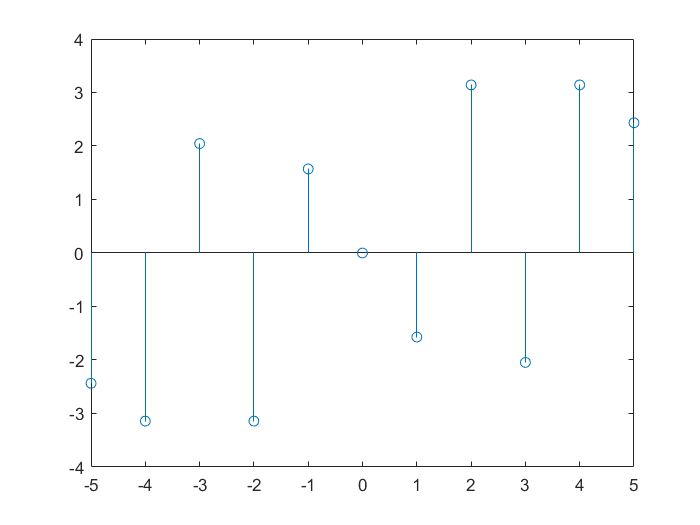

figure
stem(k,phase)

function y=f(t)
    f0=60;
    T0=1/f0;
    w0=(2*pi)*f0;
    y=(mod(t,T0)<T0/2).*sin(w0*t);
end
   
